## Graficar un polinomio

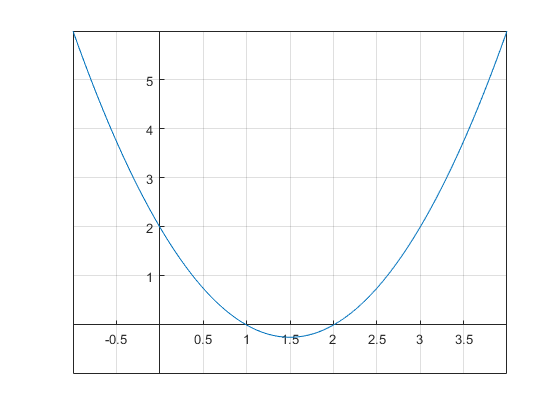

x=-1:0.01:4;
y=x.^2-3*x+2;
figure(1);
plot(x,y)
grid on

ejes=gca
ejes.XLim=[-1,4];

ejes.XAxisLocation = 'origin';
ejes.YAxisLocation = 'origin';

## Raices a partir de un vector con los valores del polinomio

parabola = [1 -3 2];
raices=roots(parabola)

raices =      2
     1


## Polinomio a partir de raices

raices=[2;1]; % raices en vertical, polonomios en horizontal

poly(raices) % el orden de las raices no importa, el de los valores del polinomio si.

ans =      1    -3     2


raices=[1;2];

poly(raices) % el polinomio queda en el mismo orden.

ans =      1    -3     2


parabola=[2 -3 1] % ahora si deberia cambiar, porque cambian los valores de los grados del polinomio al cambiar el orden. 

parabola =      2    -3     1



raices=roots(parabola)

raices =     1.0000
    0.5000


## 1. Obtener un polinomio que tenga tres raíces x1 = -1, x2 = 1, y x3 = 2

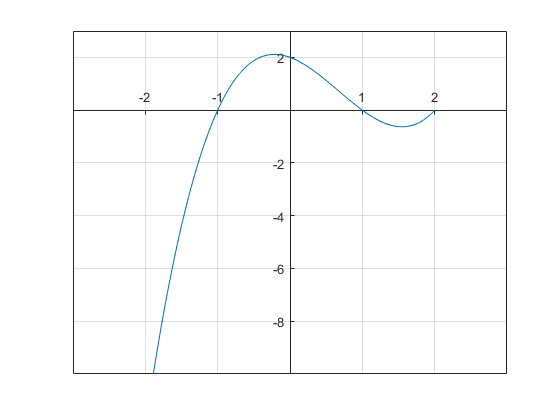

raices=[-1;1;2];
polinomio=poly(raices);

x=-2:0.01:2;
y=x.^3-2*x.^2-x+2; % polinomio en funcion de x, a partir de los valores y lugares(grados) de la variable polinomio.

figure(1)
plot(x,y)
grid on;
ejes=gca;
ejes.XAxisLocation='origin';
ejes.YAxisLocation='origin';
axis([-3 3 -10 3]) 

## 2. Hallar las raíces de un polinomio de grado 4

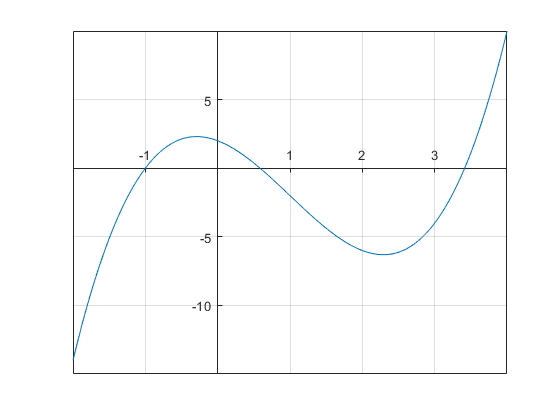

x=-2:0.01:4;
y =x.^3-3*x.^2- 2*x+2;
polinomio=[1,-3,-2,2];
figure(1)
plot(x,y)
grid on;
ejes=gca;
ejes.XAxisLocation='origin';
ejes.YAxisLocation='origin';

raices=roots(polinomio)

raices =     3.4142
   -1.0000
    0.5858


## 3. Hallar las raíces de una parábola que no corta al eje x

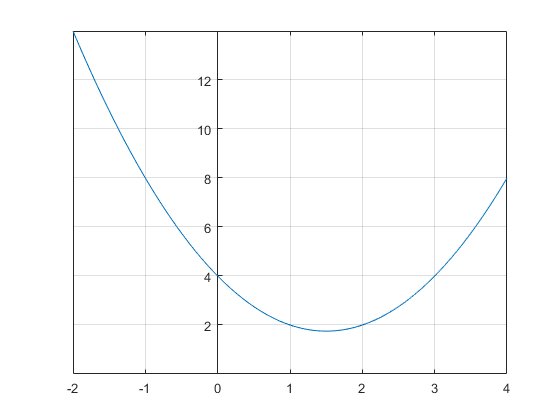

x=-2:0.01:4;
y=x.^2-3*x+4;

figure(1)
plot(x,y)
grid on;
ejes=gca;
ejes.XAxisLocation='origin';
ejes.YAxisLocation='origin';


polinomio=[1;-3;4];
raices=roots(polinomio)

raices =    1.5000 + 1.3229i
   1.5000 - 1.3229i


## 4. Hallar las raíces de una parábola que corta al eje x en un solo punto

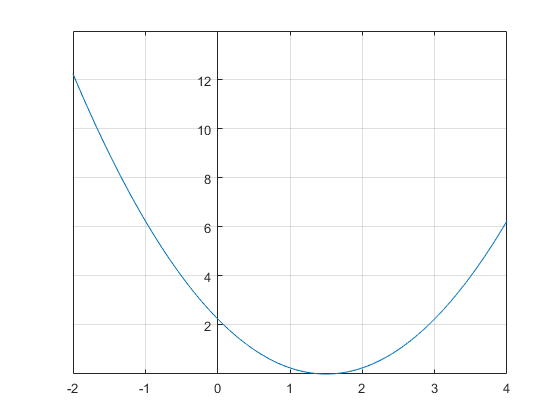

x=-2:0.01:4;
y=x.^2-3*x+2.25;

figure(1)
plot(x,y)
grid on;
ejes=gca;
ejes.XAxisLocation='origin';
ejes.YAxisLocation='origin';

polinomio=[1;-3;2.25];
raices=roots(polinomio)

raices =     1.5000
    1.5000


## Ejemplo paso a paso

raices=[-1;0;1+0.5i;1-0.5i]; % raices a partir del grafico, con parte real y parte imaginaria
polinomio=poly(raices)

polinomio =     1.0000   -1.0000   -0.7500    1.2500         0


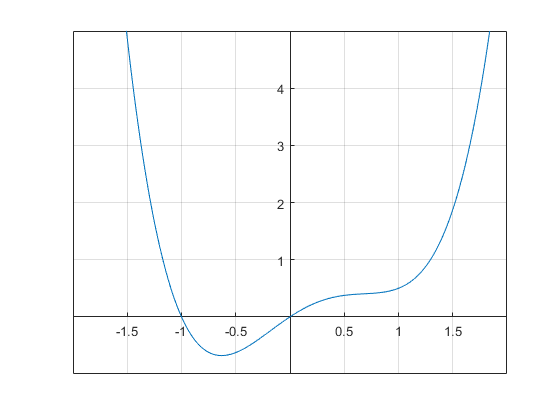

y=x.^4-x.^3-0.75*x.^2+1.25*x; % polinomio armado en funcion de x
x=-2:0.01:2;

figure(1)
plot(x,y)
grid on;
ejes=gca;
ejes.XAxisLocation='origin';
ejes.YAxisLocation='origin';
axis([-2 2 -1 5])

## 5. Hallar un polinomio conociendo el gráfico de dónde se ubican sus raíces en el plano complejo

raices=[-1.45;0;1+0.5i;1-0.5i];

polinomio=poly(raices)

polinomio =     1.0000   -0.5500   -1.6500    1.8125         0


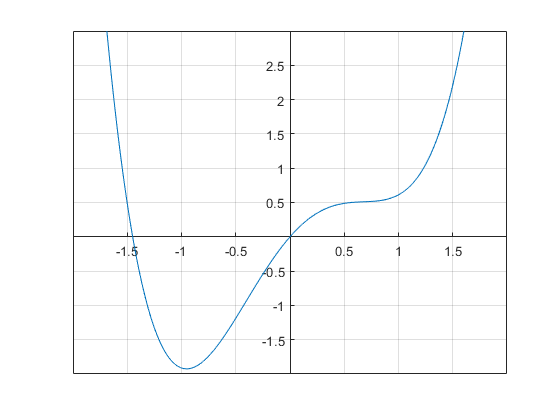


y=polinomio(1,1)*x.^4+polinomio(1,2)*x.^3+polinomio(1,3)*x.^2+polinomio(1,4)*x+polinomio(1,5); % polinomio armado en funcion de x
x=-2:0.01:2;

figure(1)
plot(x,y)
grid on;
ejes=gca;
ejes.XAxisLocation='origin';
ejes.YAxisLocation='origin';
axis([-2 2 -2 3])

## Asociación entre una función temporal (audio) y un polinomio. Ejemplo paso a paso.

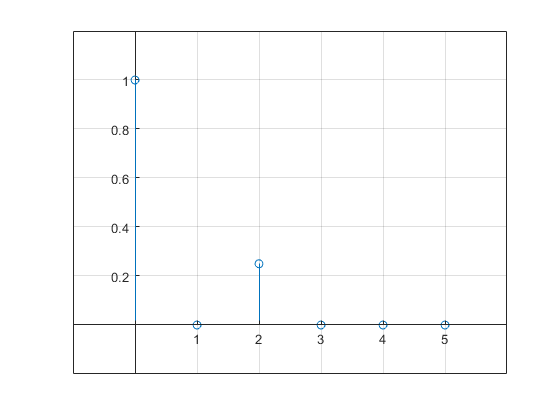


ceros=[0;0;0;0.5i;-0.5i]; % raices o ceros del grafico.

polinomio=poly(ceros);

n=0:5; % si tenemos 5 raices, tenemos 6 terminos.

stem(n,polinomio);

grid on;
ejes=gca;
ejes.XAxisLocation='origin';
ejes.YAxisLocation='origin';
axis([-1 6 -0.2 1.2])

## Ejemplo paso a paso

## Obtener la Transformada z de la siguiente señal discreta (correspondiente a una respuesta al impulso)

h=[1,0,0,0.5,0,0]; 

%{

 H= 1 + 0.5.^-3

 Ahora, sacando las raices con root(), tenemos los ceros.
 Los polos van a salir de la cantidad de raices/grado del polinomio.


%}

ceros=roots(h)

ceros =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.7937 + 0.0000i
   0.3969 + 0.6874i
   0.3969 - 0.6874i


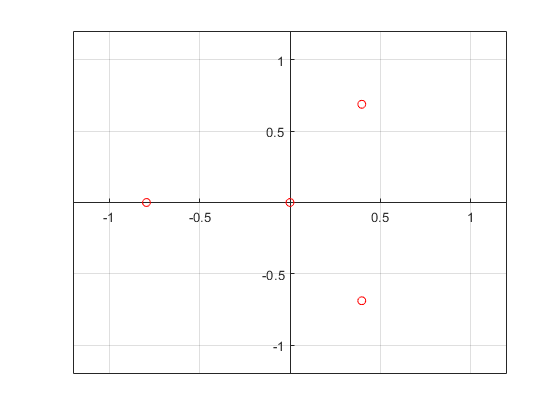


% grafico

plot(real(ceros),imag(ceros),'or');
grid on;
ejes=gca;
ejes.XAxisLocation='origin';
ejes.YAxisLocation='origin';
axis([-1.2 1.2 -1.2 1.2])

## 8. Dado el siguiente polinomio en forma desarrollada, encuentre su expresión factorizada.

polinomio=[1,-7,14,8];

raices=roots(polinomio)

raices =    3.7296 + 1.8748i
   3.7296 - 1.8748i
  -0.4591 + 0.0000i


% y que pasa en este caso que tengo parte imaginaria?

## 9. Ejercicio de multiplicación de polinomios - convolución

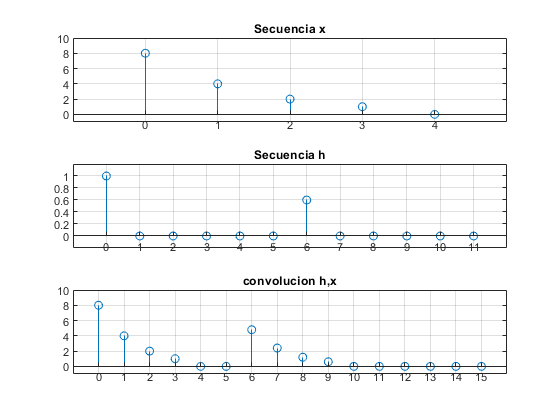

x=[8 4 2 1 0];
h=[1 0 0 0 0 0 0.6 0 0 0 0 0];

y=conv(h,x);

subplot(3,1,1)

n=0:length(x)-1;

stem(n,x)
grid on;
title('Secuencia x')
ejes=gca;
ejes.XAxisLocation='origin';
ejes.XAxisLocation='origin';
yticks(0:2:10);
xticks(n);
axis([-1 5 -1 10])
subplot(3,1,2)

n1=0:length(h)-1;

stem(n1,h)
grid on;
title('Secuencia h')
ejes=gca;
ejes.XAxisLocation='origin';
ejes.XAxisLocation='origin';
yticks(0:0.2:8);
xticks(n1);
axis([-1 12 -0.2 1.2])

subplot(3,1,3)


n2=0:length(y)-1;

stem(n2,y)
grid on;
title('convolucion h,x')
ejes=gca;
ejes.XAxisLocation='origin';
ejes.XAxisLocation='origin';
yticks(0:2:10);
xticks(n2);
axis([-1 16 -1 10])